# **	Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 4 part 2: exercise 01 - Identifying Round Objects

extracted from: [https://es.mathworks.com/help/images/identifying-round-objects.html?searchHighlight=round%20object&s_tid=doc_srchtitle](https://es.mathworks.com/help/images/identifying-round-objects.html?searchHighlight=round%20object&s_tid=doc_srchtitle)

## Questions

- Run the program. This example shows how to classify objects based on their roundness using `bwboundaries`, a boundary tracing routine.

- Load the image `'google.jpg'` and determine, using some parameter calculated in the `regionprops` function, if the objects are concave or convex. Note: In this question you must take into account that the foreground is dark and the background is light, therefore you must modify steps 2 and 3 to get a correct labeling. 

Step 1) Read Image

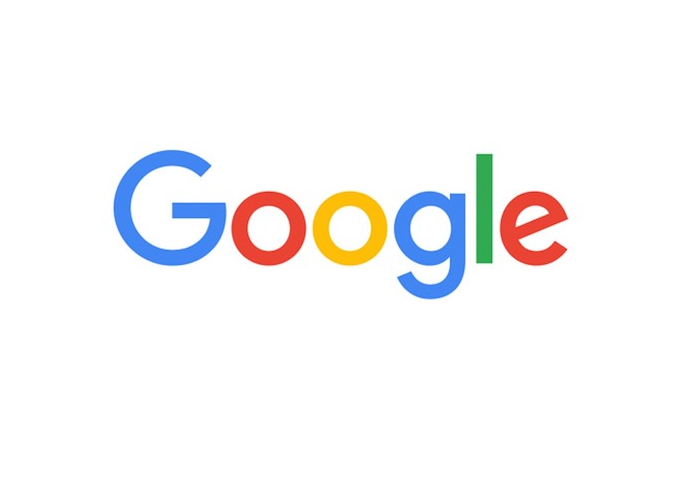

RGB = imread('google.jpg');
imshow(RGB);

Step 2) Threshold the Image

Convert the image to black and white in order to prepare for boundary tracing using `bwboundaries`.

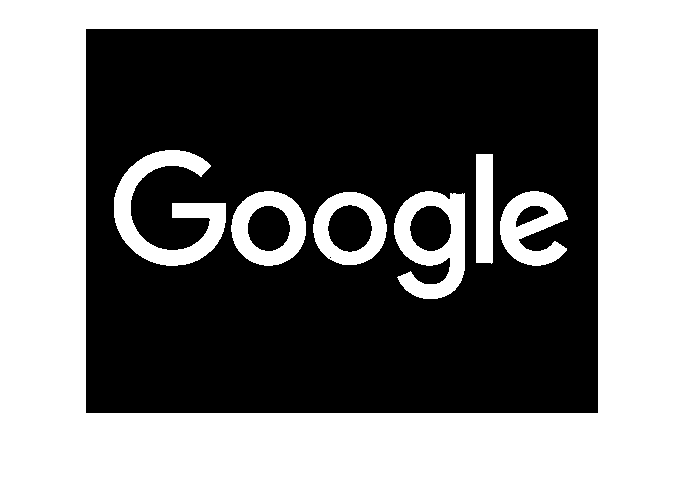

I = rgb2gray(RGB);
bw = imbinarize(I);
bw= 1-bw; %Ponemos el fondo en negro y los objetos en blanco para poder utilizar 
          %los mismos metodos que en el ejemplo
imshow(bw)

Step 3) Remove the Noise

Using morphology functions, remove pixels which do not belong to the objects of interest.

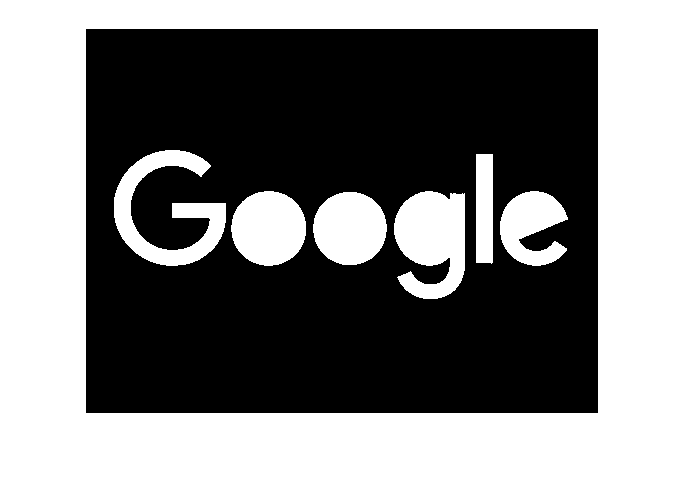

% remove all object containing fewer than 30 pixels
bw = bwareaopen(bw,30);

% fill any holes, so that regionprops can be used to estimate
% the area enclosed by each of the boundaries
bw = imfill(bw,'holes');

imshow(bw)

Step 4) Find the Boundaries

Concentrate only on the exterior boundaries. Option 'noholes' will accelerate the processing by preventing `bwboundaries` from searching for inner contours.

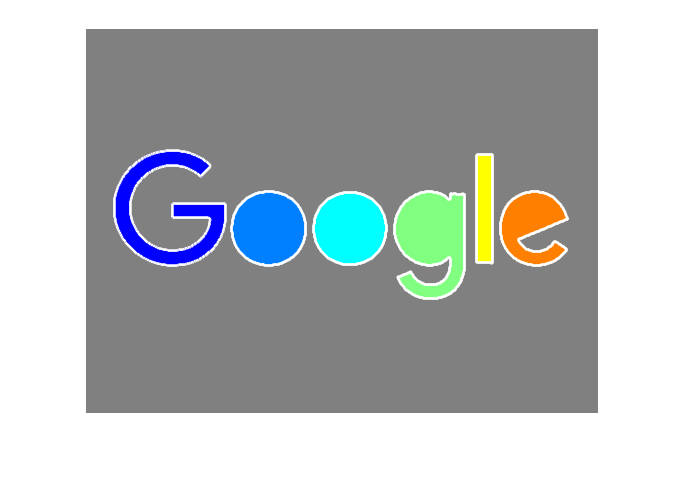

[B,L] = bwboundaries(bw,'noholes');

% Display the label matrix and draw each boundary
imshow(label2rgb(L, @jet, [.5 .5 .5]))
hold on
for k = 1:length(B)
  boundary = B{k};
  %Mostramos los bordes de los objetos
  plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end

Step 5) Determine which Objects are Convex

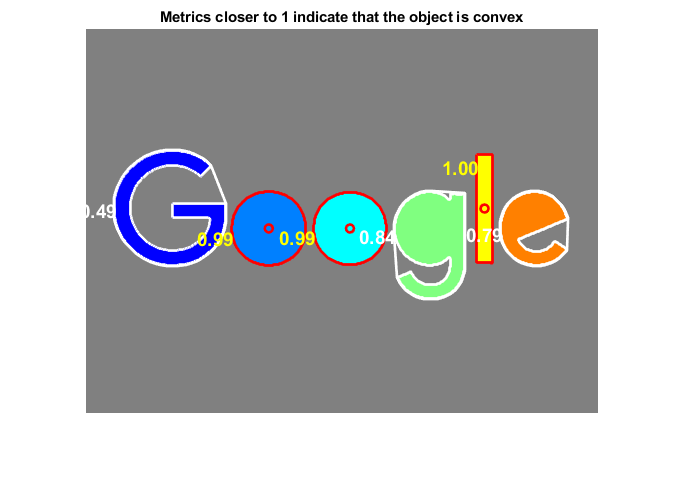

stats = regionprops(L,'Area','Centroid','ConvexArea','ConvexHull');

threshold = 0.94; %Umbral a partir del cual consideramos que el objeto es convexo

% loop over the boundaries
for k = 1:length(B)

  % obtain (X,Y) boundary coordinates corresponding to label 'k'
  boundary = B{k};

  % obtain the area calculation corresponding to label 'k'
  area = stats(k).Area;
  
  % compute the convex metric
  metric = area/stats(k).ConvexArea;
  
  % display the results
  metric_string = sprintf('%2.2f',metric);

  % Mostramos los objetos utilizamos el color rojo para los considerados convexos
  %y el blanco para los que no
  
  if metric > threshold
    %Mostramos el centroide del objeto
    centroid = stats(k).Centroid;
    plot(centroid(1),centroid(2),'ro', 'LineWidth', 2);
    
    %Mostramos los borde del objeto
    plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);
    text(boundary(1,2)-35,boundary(1,1)+13,metric_string,'Color','y',...
       'FontSize',14,'FontWeight','bold');
   
  else
      %Mostramos el ConvexHull del objeto
      plot(stats(k).ConvexHull(:,1),stats(k).ConvexHull(:,2),'w','LineWidth', 2);
      %Mostramos los bordes del objeto
      text(boundary(1,2)-35,boundary(1,1)+13,metric_string,'Color','w',...
       'FontSize',14,'FontWeight','bold');
  end
  
  
  
end

title(['Metrics closer to 1 indicate that ',...
       'the object is convex']);

*Copyright 1993-2015 The MathWorks, Inc.*